# Perform Speech-to-Text using 3rd party Speech APIs

This example shows how to perform speech-to-text transcription in MATLAB®. The `speech2text` function enables you to interface with 3rd party speech APIs.

## Introduction

The `speech2text` function provides the ability to use 3rd party speech APIs to perform speech-to-text transcription. The function supports the following 3rd party tools:

- [Google™ Cloud Speech-to-Text API](https://cloud.google.com/speech-to-text/)

- [IBM™ Watson Speech to Text API](https://www.ibm.com/watson/services/speech-to-text/)

- [Microsoft™ Azure Speech Services API](https://azure.microsoft.com/en-us/services/cognitive-services/speech-to-text/)

To use the `speech2text` function, you must have the following products installed:

- MATLAB release R2017a or above

- Audio Toolbox™

## Set up 3rd Party API

Before you start using the `speech2text` function, you need to perform some steps to set up the API. 

First run the `setup.m `script from the downloaded speech2text folder. This makes sure the downloaded files are added to your MATLAB path and the **Speech to Text** automation algorithm is installed in Audio Labeler app if you are running MATLAB R2019b.

Next, you will be creating an account with the cloud service and generating an authorization key. Google, IBM, and Microsoft APIs have different requirements to set up an account and generate an authorization key.

#### Google Cloud Speech-to-Text

Using the Google Cloud Speech-to-Text API requires an API key for authorizing the request. The following steps describe how to create the API key. This is also described in the [Google documentation](https://cloud.google.com/docs/authentication/api-keys):

1. Navigate to the [APIs & Services->Credentials](https://console.cloud.google.com/apis/credentials) panel in Cloud Platform Console.

2. Select **Create credentials**, then select **API key** from the drop-down menu. 

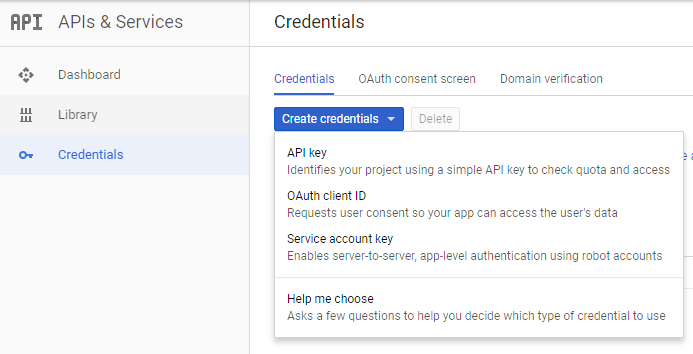

3. Click the **Create** button. A dialog box appears which displays your newly created key.

4. Once you have the API key, download it and create a JSON file such that:

    a. JSON file should have an attribute called: "key" (case sensitive). For example, if the API key generated is ABCDefgh, then the file will have the attribute "key", and value "ABCDefgh", as shown below:

    

    b. Optionally you can specify the "recongnizeUrl" (case sensitive) attribute. If you don't specify this, the recognizeUrl defaults to `https://speech.googleapis.com/v1/speech:recognize`

    c. Save the file as "Google_Credentials_Speech2text.json" to a **secure** location.

The `speech2text` function will look for "Google_Credentials_Speech2text.json" to obtain the API key, which the Google Speech API requires for authentication.

#### IBM Watson Speech to Text

IBM Speech to Text API is offered through IBM Cloud services which now uses token-based Identity and Access Management (IAM) authentication. To begin, you must create an IBM Cloud account, a Speech to Text service instance, and go to the service dashboard and copy your credentials - API Key and URL values.

This information is also described in the  [IBM Speech to Text documentation](https://console.bluemix.net/docs/services/speech-to-text/getting-started.html#gettingStarted):

1. Go to the [Speech to Text service](https://console.bluemix.net/catalog/services/speech-to-text/) and sign up for a free IBM Cloud account or log in to your existing account.

2. After you log in, enter speech-to-text-tutorial in the Service name field of the Speech to Text page. Click **Create**.

3. Copy the credentials created:

    a. Go to the [IBM Cloud dashboard](https://console.bluemix.net/dashboard/apps)

    b. Select the Speech to Text service instance.

    c. Click **Show Credentials" under *Manage**.

    d. Copy the API Key and URL values.

4. Write the API Key and URL values to a JSON file:

    a. For example, if the API Key generated is "abcd-1234-WXYZ" and the URL is "https://stream.watsonplatform.net/speech-to-text/api" then the JSON file will have the attribute "apikey" with value "abcd-1234-WXYZ" and "url" with value "https://stream.watsonplatform.net/speech-to-text/api", as shown below. In some cases, speech2text doesn't work if the URL is not the same as the one below. If you encounter this problem, try using the URL below and not the one shown in your IBM Cloud dashboard.

    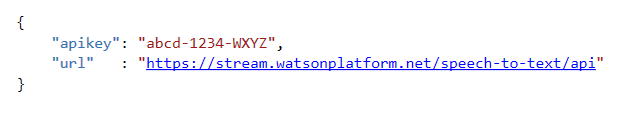

    b. Save the file as "IBM_Credentials_Speech2text.json" to a **secure** location.

The `speech2text` function will look for "IBM_Credentials_Speech2text.json" to obtain the API Key and URL.

#### Microsoft Azure Speech API

Microsoft's Speech to Text API is part of Microsoft Azure Speech Services, and requires subscription keys. You can obtain the keys from the Cognitive Services subscription page by following the steps below. This information is also described in [Microsoft Speech Service Documentation](https://docs.microsoft.com/en-us/azure/cognitive-services/speech-service/get-started):

1. Go to the Cognitive Services subscription, and login/create your Microsoft Azure account.

2. Select Speech Services and click on **Get API Key**.

3. This returns a primary and secondary key – "Key 1" and "Key 2". Select your location/country and get the endpoint URI. Copy these to create a JSON file:

    a. JSON file should have four attributes: "key1", "key2", "tokenUri" and "requestUri" (case sensitive). The URIs can also be obtained from [Speech Service REST APIs documentation](https://docs.microsoft.com/en-us/azure/cognitive-services/Speech-Service/rest-apis). For example, if the Key 1 generated is abcd1235 and Key 2 is 5678wxyz then the JSON file will have the attribute "key1" with value "abcd1235" and "key2" with value "5678wxyz" and the URIs as shown below:

    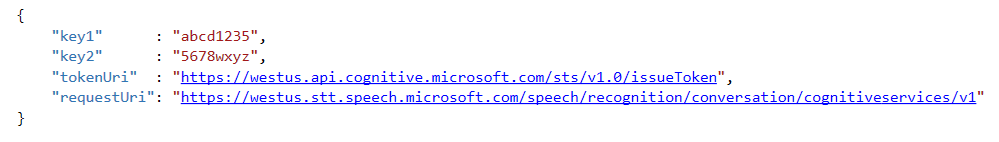

    b. Save the file as "Microsoft_Credentials_Speech2text.json" to a **secure** location.

The `speech2text` function will look for "Microsoft_Credentials_Speech2text.json" to obtain the subscription key.

If the JSON file is not on MATLAB search path, the `speech2text` function will prompt you to provide the path. This path is then saved to MATLAB search path.

## Create speechClient

After getting the authorization credentials from the respective API, you are ready to perform speech to text transcription. The first step is to set up a `speechClient` object with the speech API and its properties.

This example uses the Google Speech API, and specifies the `languageCode` option to 'en-US':

speechObject = speechClient('Google','languageCode','en-US')

speechObject =   GoogleSpeechClient with properties:

       Name: "Google"
    Options: [1×1 struct]
    TimeOut: 10


#### Input Parameters

Since each of the APIs support varied number of input parameters and the parameters have different names, you are expected to provide the correct input for the API. If the API returns any error due to incorrect input parameters, then the `speech2text` function captures and reports the error.

#### Using Google

The name-value pairs provided with the `speechClient` object should adhere to the name-value pair that the Google Cloud Speech-to-Text API accepts, as described in their [documentation](https://cloud.google.com/speech/reference/rest/v1/RecognitionConfig).

#### Using IBM

For the IBM Speech to Text API, the name-value pairs provided to the `speechClient` object should adhere to the name-value pair that the IBM API accepts, as described in their [documentation](https://www.ibm.com/watson/developercloud/speech-to-text/api/v1/#recognize_sessions_nonmp18). For example, to specify the keywords to IBM, you also need to specify the threshold value:

speechObjectIBM = speechClient('IBM','keywords',"example,keywords",'keywords_threshold',0.5);
speechObjectIBM.Options

ans = struct with fields:
              keywords: "example,keywords"
    keywords_threshold: 0.5000


#### Using Microsoft

For Microsoft Speech to Text API the name-value pairs provided with the `speechClient` object should adhere to the name-value pair as described in their [documentation](https://docs.microsoft.com/en-us/azure/cognitive-services/Speech-Service/rest-apis#query-parameters).

If no parameter names and values are specified, then the API uses default values. Refer to the respective API’s documentation for more information on default values.

## Perform Speech-to-Text Transcription

Read a speech signal, and get the speech samples (`y`) and sampling frequency (`fs`). This example uses a speech signal which counts numbers from 1 to 10 in English.

[y,fs] = audioread('Counting-16-44p1-mono-15secs.wav');

Call the `speech2text` function and pass the `speechClient` object with `y` and `fs`

tableOut = speech2text(speechObject,y,fs)

tableOut = 5×2 table
              Transcript               Confidence
    _______________________________    __________

    "1"                                 0.76878  
    " 2"                                0.78807  
    " 3"                                0.74369  
    " 4"                                0.80068  
    " five six seven eight nine 10"     0.80835  


Call the `speech2text` function and pass the `speechClient` object with `y`, `fs`, and `HTTPTimeOut`

tableOut = speech2text(speechObject,y,fs,'HTTPTimeOut',25)

tableOut = 5×2 table
              Transcript               Confidence
    _______________________________    __________

    "1"                                 0.76878  
    " 2"                                0.78807  
    " 3"                                 0.7437  
    " 4"                                0.80068  
    " five six seven eight nine 10"     0.80835  


#### Output Format

The output is returned as a table with Transcript and Confidence values. If there were any errors, then the output provides the error code and the error message.

If you configured the `speechClient` to return additional results, then the output of `speech2text` returns the additional results as part of the output table. For example, if you had set the maximum alternatives parameter to 3 and if there are 3 alternatives returned by the Google API then the output will have three columns: `TRANSCRIPT`, `CONFIDENCE` and `ALTERNATIVES`. The `ALTERNATIVES` will be another table that contains the `TRANSCRIPT` and `CONFIDENCE` of the alternate transcription of the speech signal

speechObject = speechClient('Google','languageCode','en-US','maxAlternatives',3);
tableOut = speech2text(speechObject,y,fs)

tableOut = 5×3 table
              Transcript               Confidence    Alternatives
    _______________________________    __________    ____________

    "1"                                 0.76878       {2×1 cell} 
    " 2"                                0.78807       {2×1 cell} 
    " 3"                                 0.7437       {2×1 cell} 
    " 4"                                0.80068       {2×1 cell} 
    " five six seven eight nine 10"     0.80835       {2×1 cell} 


## Perform Speech-to-Text in Audio Labeler

You can also perform speech-to-text transcription interactively using the [Audio Labeler](https://www.mathworks.com/help/audio/ref/audiolabeler-app.html) app starting in MATLAB R2019b.

Once you have run the `setup.m` script in the downloaded speech2text folder, open Audio Labeler app from the MATLAB apps gallery or by running `audioLabeler` command from MATLAB command prompt. The Audio Labeler app's toolstrip will show a **Speech to Text** button under **AUTOMATION** section.

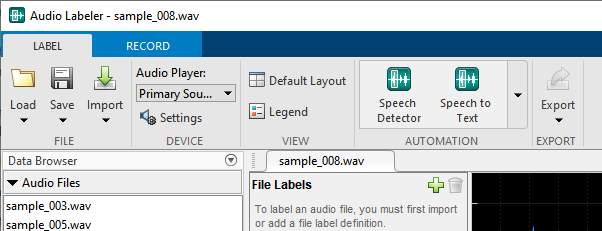

Load the audio files you want to transcribe and click the **Speech to Text** button. This will open a new tab by the same name. 

You can use the controls in the **Speech to Text** tab to interactively perform speech to text transcription, listen and edit the results, tweak optional parameters supported by the cloud speech service, and automate the transcription over multiple audio files. See [Label Audio Using Audio Labeler](https://www.mathworks.com/help/audio/ug/audio-labeler-walkthrough.html) example for more details about using the Audio Labeler app.

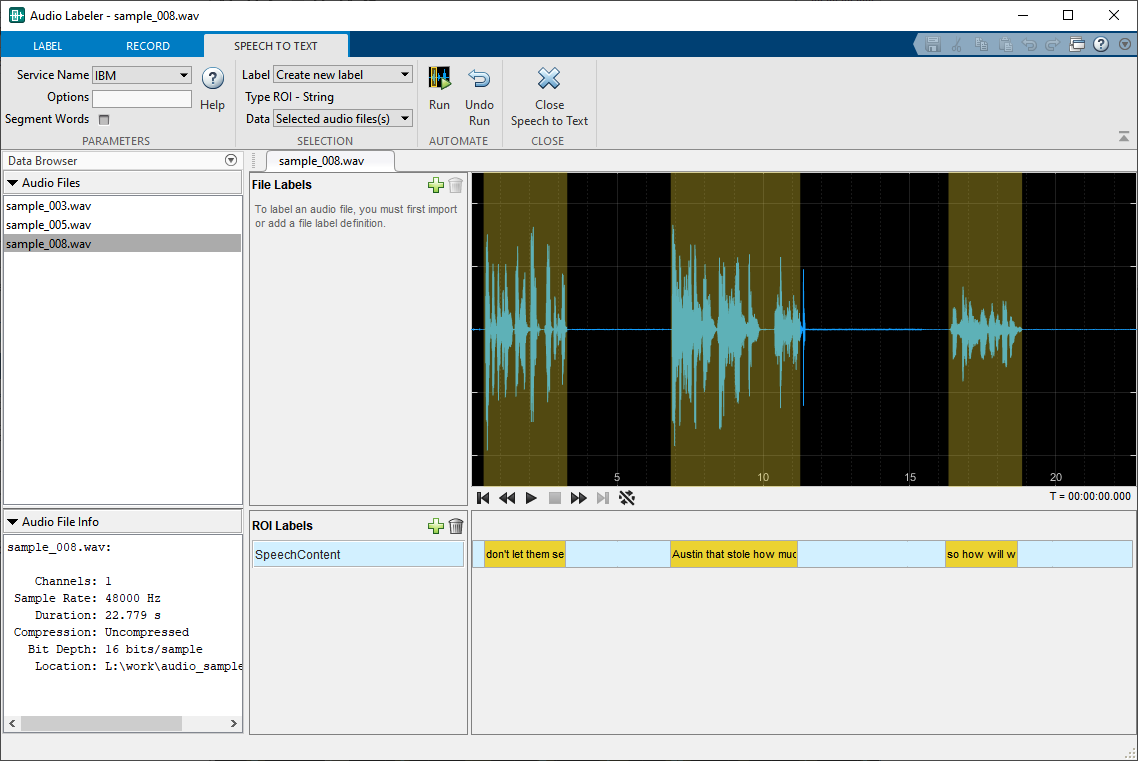

## Billing Details

MathWorks provides the `speech2text` function free of charge. However, the 3rd party speech APIs are not free. Consult the individual API documentation for pricing details:

- [Google Cloud Speech Pricing](https://cloud.google.com/speech/pricing)

- [IBM Watson Speech to Text Pricing](https://console.bluemix.net/docs/services/speech-to-text/faq-pricing.html#pricing)

- [Microsoft Azure Speech Services Pricing](https://azure.microsoft.com/en-us/pricing/details/cognitive-services/speech-services)

*Copyright 2017-2019 The MathWorks, Inc.*